# Load data

clear all; close all;
addpath('./MatlabFuncs/')

load('Data\Param_Fit2.mat', 'x_both');
load('Data\Param_Fit3.mat', 'x_all');

xdata = [0, .2, .5, 1, 2, 5, 10, 20, 50, 100];

run('./MatlabFuncs/FuncGenerator.m');

auxins = logspace(-2,2,100);

# Time Trajectories 

## *Varied initial Conditions*

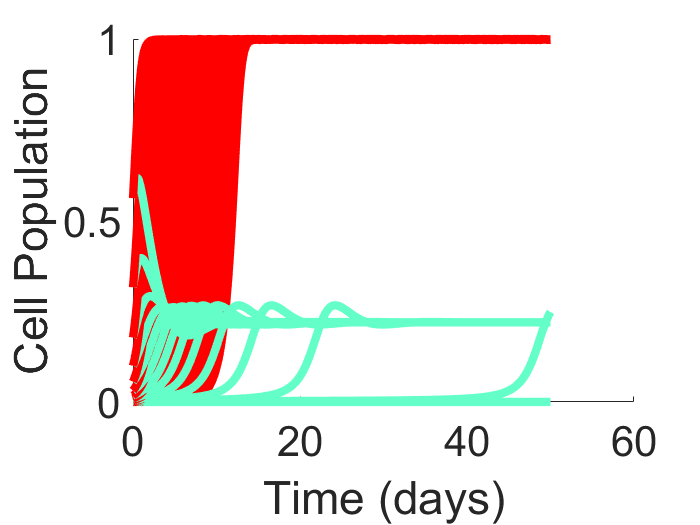

tspan = linspace(0, 50 * 24, 1000);

%Set known values
B_ext = 50; %ug
AP = 20; %uM

c0 = logspace(-5, -0.25, 20);
a0 = 10; %linspace(5,20,5);
[A1, N1] = meshgrid(a0,c0);

figure(1);

cir_on = [];
cir_off = [];

for i = 1 : numel(A1)
    y0 = [A1(i), N1(i)];
    [t,f] = ode45(@(t,y) DynSys(t,y,x_both,B_ext,AP),tspan,y0');
    [tc,fc] = ode45(@(t,y) DynSys(t,y,x_both,0,0),tspan,y0');
    
    cir_on = [cir_on, f(:,2)];
    cir_off = [cir_off, fc(:,2)];
    
    hold on;
    plot(tspan./24,f(:,2),'k','Linewidth',5,'Color',[100,255,201]./255)
    plot(tspan./24,fc(:,2),'k','Linewidth',5,'Color',[1,0,0])
end

save("Data\Dynamcs.mat", "cir_on", "cir_off", "tspan");

xlabel('Time (days)')
ylabel('Cell Population')

ax1 = gca;
ax1.FontSize = 25;